# **2108332 Adjustment Computation**

## **LAB 7** General Mathematical Model

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

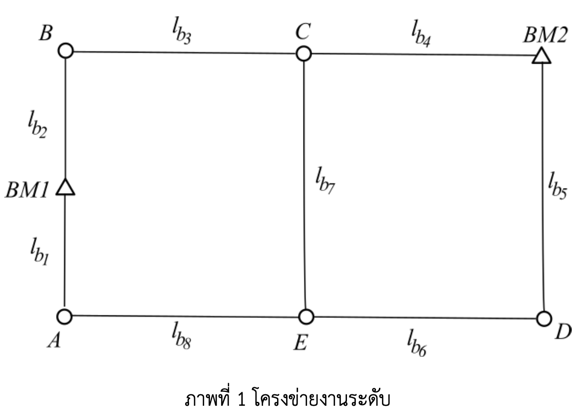

ภาพที่ 1 แสดงการรังวัดโครงข่ายงานระดับ ลูกศรในภาพแสดงถึงทิศทางการรังวัด ผลการรังวัดแสดงในตารางต่อไปนี้

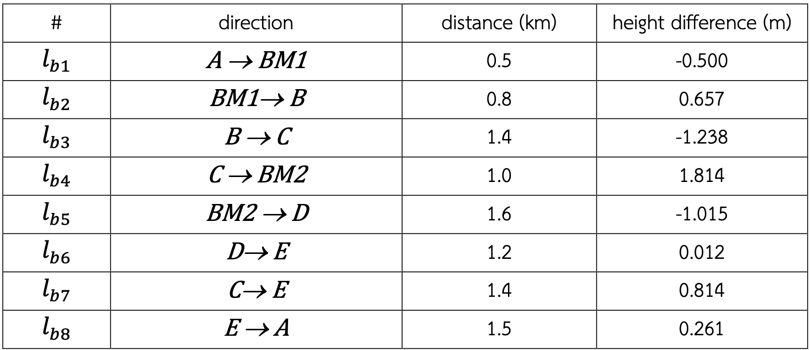

#### ค่าความสูงของจุด $BM1$ และ $BM2$ คือ  29.499 ม.และ 30.737 ม. ตามลำดับ กำหนดให้น้ำหนักของค่ารังวัดแต่ละค่าเป็นอิสระต่อกัน และแปรผกผันกับระยะทาง ให้เขียนสคริปต์ MATLAB เพื่อปรับแก้ค่ารังวัดโดยวิธีกำลังสองน้อยที่สุดแบบใช้แบบจำลองทั่วไป กำหนดให้มีเพียง 4 พารามิเตอร์ สคริปต์จะต้องแสดงค่ารังวัดที่ปรับแก้แล้ว และค่าระดับของจุด A, B, C, D และ E

clear
format long g

BM1 = 29.499;
BM2 = 30.737;

lb = [-0.500;0.657;-1.238;1.814;-1.015;0.012;0.814;0.261];

P = [1/0.5;1/0.8;1/1.4;1/1;1/1.6;1/1.2;1/1.4;1/1.5];
P_diagonal = diag(P);

A = [-1 0 0 0;
    0 1 0 0;
    0 -1 1 0;
    0 0 -1 0;
    0 0 0 1;
    0 0 0 0;
    0 0 0 0];

B = [-1 0 0 0 0 0 0 0;
    0 -1 0 0 0 0 0 0;
    0 0 -1 0 0 0 0 0;
    0 0 0 -1 0 0 0 0;
    0 0 0 0 -1 0 0 0;
    1 1 1 0 0 0 1 1;
    0 0 0 1 1 1 -1 0];

C = [BM1;
    -BM1;
    0;
    BM2;
    -BM2;
    0;
    0];

W = B * lb + C;

M = B * (P_diagonal)^-1 * B';
Xa = -(A' * M^-1 * A)^-1 * A' * M^-1 * W

Xa =           29.9985030409731
          30.1573188220231
          28.9216267605634
          29.7231498079385


V = -(P_diagonal)^-1 * B' * M^-1 * (A * Xa + W);
La = lb + V

La =         -0.499503040973124
         0.658318822023055
         -1.23569206145966
          1.81537323943661
         -1.01385019206146
        0.0128623559539142
          0.81438540332906
         0.262490877080671


H_E = La(6) + Xa(4)

H_E =           29.7360121638925
